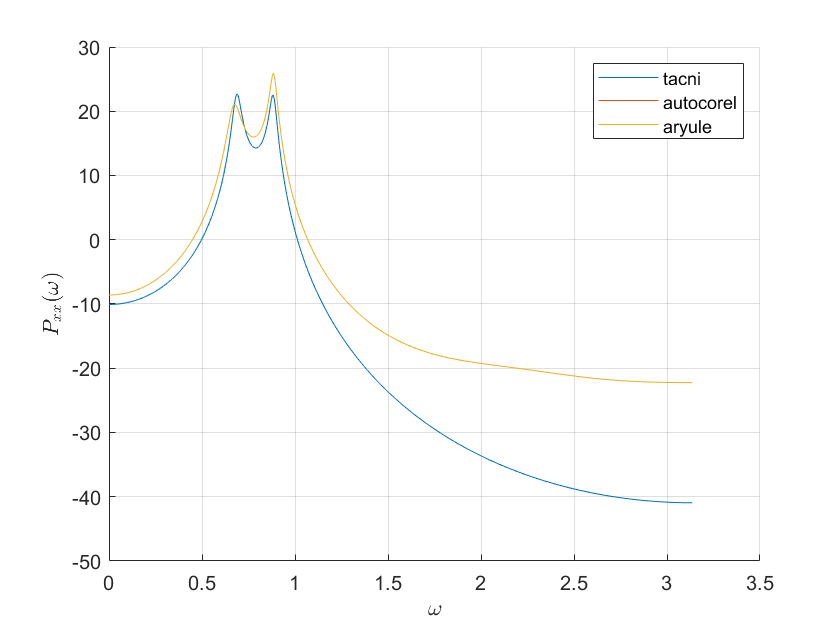

clear all;
close all;
rng default;
s = 0.1;
N = 256;
p = 7;
u = randn(1, N)*s;
a = [1 -2.76 3.809 -2.654 0.924];


x = filter(1, a, u);

[H, W] = freqz(1, a);
f = W/(2*pi);
sum = 0;

Pxx = s^2*abs(H).^2;

[a1, s1] = autocorel_my(x, p);
sum = 0;
[H, W] = freqz(1, a1, W);
Pxx1 = s1*abs(H).^2;

[a2, s2] = aryule(x, p);
[H, W] = freqz(1, a1, W);
Pxx2 = s2*abs(H).^2;

figure;

    hold all;
    plot(W, 10*log10(Pxx));
    plot(W, 10*log10(Pxx1));
    plot(W, 10*log10(Pxx2));
    legend(['tacni'], ['autocorel'],['aryule'])
    hold off;
    xlabel('$\omega$', 'Interpreter','latex');
    ylabel('$P_{xx}(\omega)$', 'Interpreter','latex');
    grid on;

    
names = {};
for k = 1 : p+ 1
    names{k} = ['a' num2str(k-1)];
end
T = array2table([[a zeros(1,p - length(a) + 1)]; a1; a2], 'VariableNames',names,...
'RowNames', {'tacni', 'autocorel','aryule'});
disp(T);

                 a0      a1        a2          a3           a4          a5          a6         a7   
                 __    _______    _____    __________    ________    _________    _______    _______

    tacni        1       -2.76    3.809        -2.654       0.924            0          0          0
    autocorel    1     -1.6908    1.402    -0.0057955    -0.13128    -0.018653    0.16433    0.11855
    aryule       1     -1.6908    1.402    -0.0057955    -0.13128    -0.018653    0.16433    0.11855



z =zpk(tf('z'));
A = a(1) + a(2)*z^(-1) +a(3)*z^(-2)+a(4)*z^(-3)+a(5)*z^(-4);
A1 = a1(1) + a1(2)*z^(-1) +a1(3)*z^(-2)+a1(4)*z^(-3)+a1(5)*z^(-4);
figure();
hold on;
pzmap(1/A); pzmap(1/A1);
legend('t', 'est');

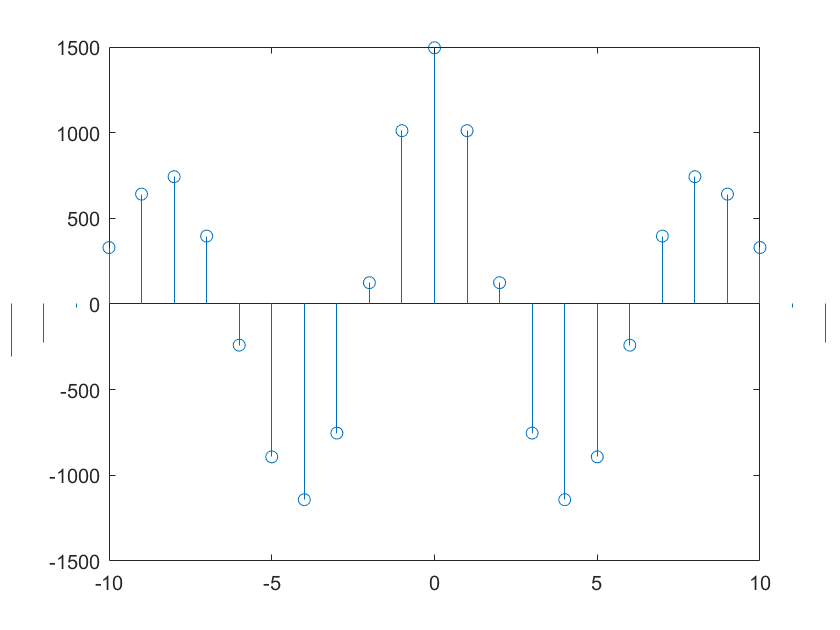

clear sum
u_hat = zeros(1, N);
for n = 1:N
    if n<=p
        u_hat(n) = sum(a1(1:n).*x(n:(-1):1));
    else
        u_hat(n) = sum(a1.*x(n:(-1):n-p));
    end   
end

ruu = xcov(u_hat);

figure();
stem(-N+1 : N-1, ruu);

xlim([-10 10])

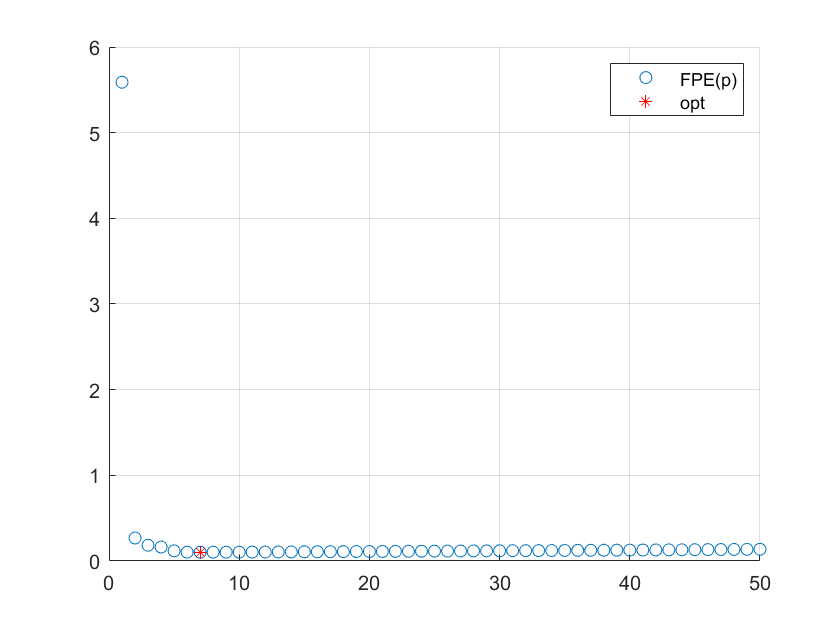

p = 1 : 50;
FPE = zeros(1,length(p));
s = zeros(1, length(p));

v = sqrt((var(x)))*randn(1, N);
x_n = x + v;

for k = 1 : length(p)
    [a1, s(k)] = autocorel(x, p(k));
    FPE(k) = (N+p(k))/(N-p(k))*s(k);
end
figure();
hold on;
plot(p, FPE, 'o');
[m, ind] = min(FPE);
plot(ind, m, 'r*');
legend('FPE(p)', 'opt')
grid on;

disp(p(ind))

     7



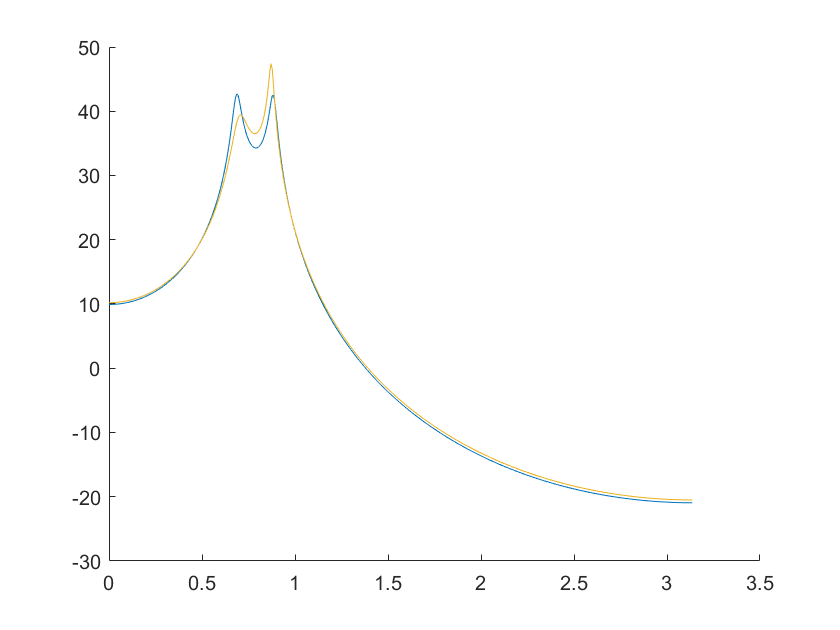

clear all;
close all;
clc;




N = 256;
p = 4;
u = randn(1, N);
a = [1 -2.76 3.809 -2.654 0.924];


x = filter(1, a, u);

[H, W] = freqz(1, a);
f = W/(2*pi);
Pxx = abs(1./(a(1) + a(2)*exp(-2i*pi*f)+ a(3)*exp(-4i*pi*f)+ a(4)*exp(-6i*pi*f)  + a(5)*exp(-8i*pi*f))).^2;

[a1, s1] = covar(x, p);
Pxx1 = s1*abs(1./(a1(1) + a1(2)*exp(-2i*pi*f)+ a1(3)*exp(-4i*pi*f)+ a1(4)*exp(-6i*pi*f)  + a1(5)*exp(-8i*pi*f))).^2;

[a2, s2] = arcov(x, p);
Pxx2 = s2*abs(1./(a2(1) + a2(2)*exp(-2i*pi*f)+ a2(3)*exp(-4i*pi*f)+ a2(4)*exp(-6i*pi*f)  + a2(5)*exp(-8i*pi*f))).^2;

figure;

    hold all;
    plot(W, 10*log10(Pxx));
    plot(W, 10*log10(Pxx1));
    plot(W, 10*log10(Pxx2));
    hold off;

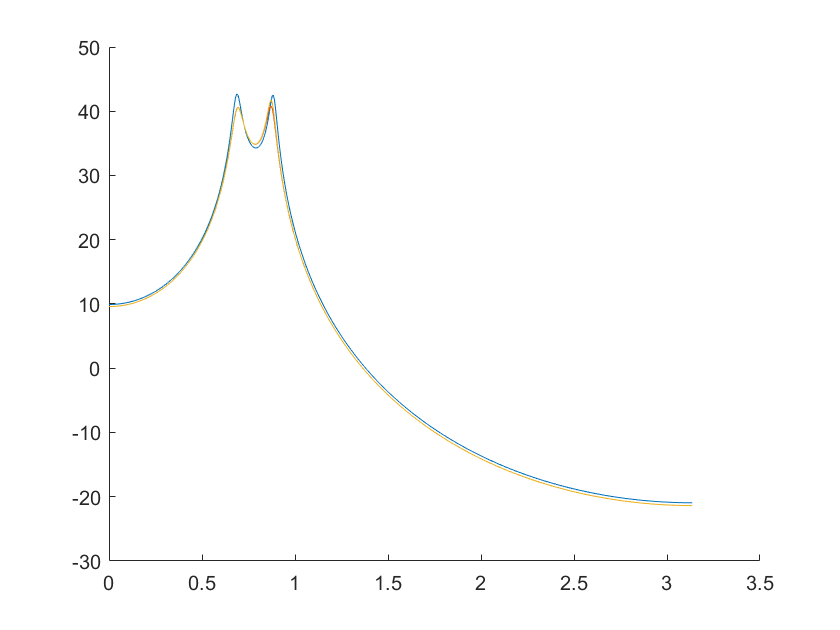

                 a0      a1         a2        a3         a4   
                 __    _______    ______    _______    _______

    tacni        1       -2.76     3.809     -2.654      0.924
    autocorel    1     -2.7542    3.7824     -2.619    0.90329
    aryule       1     -2.7576    3.7921    -2.6293    0.90786



N = 256;
p = 4;
u = randn(1, N);
a = [1 -2.76 3.809 -2.654 0.924];


x = filter(1, a, u);

[H, W] = freqz(1, a);
f = W/(2*pi);
Pxx = abs(1./(a(1) + a(2)*exp(-2i*pi*f)+ a(3)*exp(-4i*pi*f)+ a(4)*exp(-6i*pi*f)  + a(5)*exp(-8i*pi*f))).^2;

[a1, s1] = modcovar(x, p);
Pxx1 = s1*abs(1./(a1(1) + a1(2)*exp(-2i*pi*f)+ a1(3)*exp(-4i*pi*f)+ a1(4)*exp(-6i*pi*f)  + a1(5)*exp(-8i*pi*f))).^2;

[a2, s2] = arcov(x, p);
Pxx2 = s2*abs(1./(a2(1) + a2(2)*exp(-2i*pi*f)+ a2(3)*exp(-4i*pi*f)+ a2(4)*exp(-6i*pi*f)  + a2(5)*exp(-8i*pi*f))).^2;

figure;

    hold all;
    plot(W, 10*log10(Pxx));
    plot(W, 10*log10(Pxx1));
    plot(W, 10*log10(Pxx2));
    hold off;

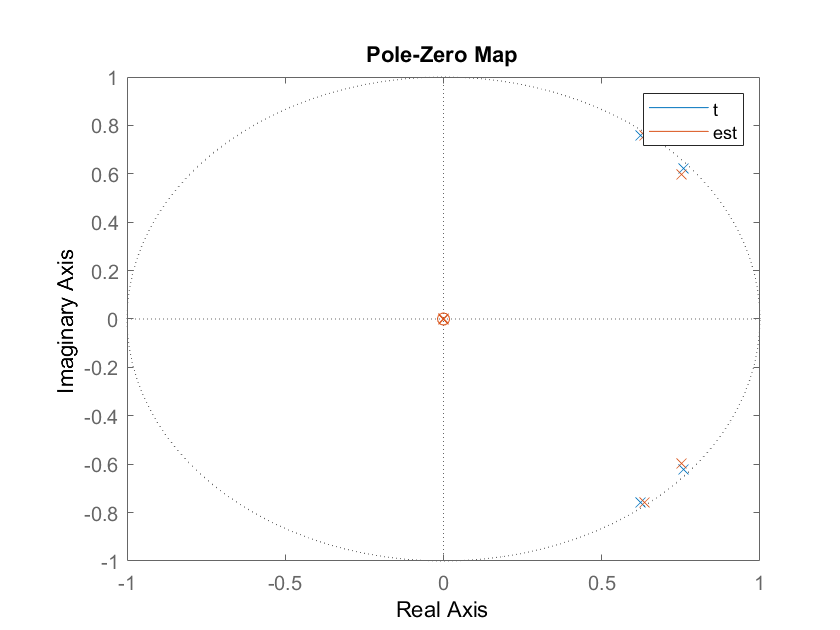

z =zpk(tf('z'));
A = a(1) + a(2)*z^(-1) +a(3)*z^(-2)+a(4)*z^(-3)+a(5)*z^(-4);
A1 = a1(1) + a1(2)*z^(-1) +a1(3)*z^(-2)+a1(4)*z^(-3)+a1(5)*z^(-4);
figure();
hold on;
pzmap(1/A); pzmap(1/A1);
legend('t', 'est');